### 1. Read the video file and define its size and frames

videosquence = 'foreman_cif-1.yuv';     % original yuv file
width = 352;                            % original yuv width
height = 288;                           % original yuv height
nframes = 10;                           % number of yuv frames
blocked_frame_cell_array = cell(1,300); % Storage for blocked frame, no meaningful use in algo., good visualizer

### 2. Define some variables, changeable in following questions.

blockSize = 64;                         % 2, 8, 64
searchRange = 4;                        % can be set to 1, 4, 8
n = 1;                                  % can be set to 1, 2, 3
I_period = 1;                           % Different I-Period values: 1, 4, 10 
QP_values = 0;                          % QP ranges for 8x8 and 16x16 blocks, {0:3:9, 1:3:10}, input one by one

### 3. Get y components and pad the frames

% extract Y, padding and blocking
A1_Q3_extract_YOnly(videosquence, height, width, nframes);

Y-only files Y!


[paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, ...
    blocked_frame_cell_array, nframes);

Y frame is split to blocks and padded as needed!


### 4. Q1

% Encoder----------------------------------------

% Define filename prefix for each single question
filename_prefix = "A2_Q1_Zout_";

% Add switchers
nRefFrames = 4;
VBSEnable = false;
MRFoverlay = 0;
FMEEnable = false;
FastME = false;

% Start the timer
tic;    

% encoding process
[psnrValues] = Encoding(filename_prefix, nframes, paddedWidth, paddedHeight, blockSize, ...
    height, width, searchRange, n, I_period, QP_values, nRefFrames, VBSEnable, MRFoverlay, ...
    FMEEnable, FastME);

Processing I-frame 1
Processing I-frame 2
Processing I-frame 3
Processing I-frame 4
Processing I-frame 5
Processing I-frame 6
Processing I-frame 7
Processing I-frame 8
Processing I-frame 9
Processing I-frame 10



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 1.37 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValues);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 50.74 dB


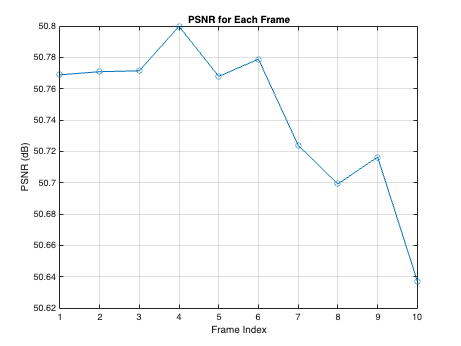


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;

% Decoder----------------------------------------
% Start the timer
tic;                                    

% decoding process
psnrValues_verify = Decoding(filename_prefix, nframes, blockSize, paddedWidth, paddedHeight, ...
    height, width, QP_values, nRefFrames, ...
    FMEEnable, FastME);

1 011 1
     0     1     0

1 011 011
     0     1     1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 010
     0     1    -1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 011
     0     1     1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 010
     0     1    -1

1 011 1
     0     1     0

1 011 011
     0     1     1

1 011 1
     0     1     0

1 011 010
     0     1    -1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 011
     0     1     1

1 011 010
     0     1    -1

1 011 011
     0     1     1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 011
     0     1     1

1 011 1
     0     1     0

1 011 1
     0     1     0

1 011 1
     0     1     0




% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.49 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 12.04 dB


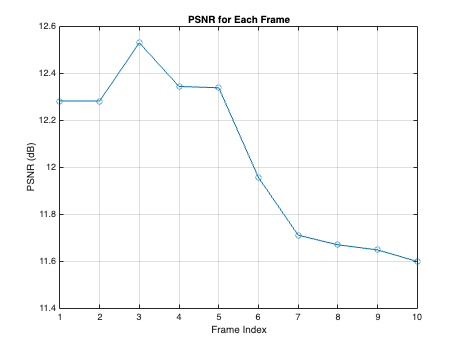


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;

### Q2. 

% Encoder----------------------------------------

% Define filename prefix for each single question
filename_prefix = "A2_Q2_Zout_";

% Add switchers
nRefFrames = 3;
VBSEnable = true;
MRFoverlay = 1;
FMEEnable = false;
FastME = false;

% Start the timer
tic;    

% encoding process
[psnrValues] = Encoding(filename_prefix, nframes, paddedWidth, paddedHeight, blockSize, ...
    height, width, searchRange, n, I_period, QP_values, nRefFrames, VBSEnable, MRFoverlay, ...
    FMEEnable, FastME);

Processing I-frame 1
Processing P-frame 2
Processing P-frame 3
Processing P-frame 4
Processing I-frame 5
Processing P-frame 6
Processing P-frame 7
Processing P-frame 8
Processing I-frame 9
Processing P-frame 10



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 5.73 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValues);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 29.29 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;                                    

% Start the timer
tic;    

% decoding process
psnrValues_verify = Decoding(filename_prefix, nframes, blockSize, paddedWidth, paddedHeight, ...
    height, width, QP_values, nRefFrames, ...
    FMEEnable, FastME);

% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.07 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 13.15 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;dTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 5.73 seconds


### Q3. 

% Encoder----------------------------------------

% Define filename prefix for each single question
filename_prefix = "A2_Q3_Zout_";

% Add switchers
I_period = 4; 
nRefFrames = 3;
VBSEnable = true;
MRFoverlay = 0;
FMEEnable = true;
FastME = false;

% Start the timer
tic;    

% encoding process
[psnrValues] = Encoding(filename_prefix, nframes, paddedWidth, paddedHeight, blockSize, ...
    height, width, searchRange, n, I_period, QP_values, nRefFrames, VBSEnable, MRFoverlay, ...
    FMEEnable, FastME);

Processing I-frame 1
Processing P-frame 2
Processing P-frame 3
Processing P-frame 4
Processing I-frame 5
Processing P-frame 6
Processing P-frame 7
Processing P-frame 8
Processing I-frame 9
Processing P-frame 10



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 7.66 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValues);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 28.48 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on; 

% Start the timer
tic;    

% decoding process
psnrValues_verify = Decoding(filename_prefix, nframes, blockSize, paddedWidth, paddedHeight, ...
    height, width, QP_values, nRefFrames, ...
    FMEEnable, FastME);

% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.20 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 13.02 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;dTime = toc;                     

fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 7.66 seconds


### Q4.

% Encoder----------------------------------------

% Define filename prefix for each single question
filename_prefix = "A2_Q4_Zout_";

% Add switchers
I_period = 4; 
nRefFrames = 3;
VBSEnable = true;
MRFoverlay = 0;
FMEEnable = true;
FastME = true;

% Start the timer
tic;    

% encoding process
[psnrValues] = Encoding(filename_prefix, nframes, paddedWidth, paddedHeight, blockSize, ...
    height, width, searchRange, n, I_period, QP_values, nRefFrames, VBSEnable, MRFoverlay, ...
    FMEEnable, FastME);

Processing I-frame 1
Processing P-frame 2
Processing P-frame 3
Processing P-frame 4
Processing I-frame 5
Processing P-frame 6
Processing P-frame 7
Processing P-frame 8
Processing I-frame 9
Processing P-frame 10



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 4.64 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValues);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 28.01 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on; 

% Start the timer
tic;    

% decoding process
psnrValues_verify = Decoding(filename_prefix, nframes, blockSize, paddedWidth, paddedHeight, ...
    height, width, QP_values, nRefFrames, ...
    FMEEnable, FastME);

% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.07 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 13.12 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValues_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;dTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 4.64 seconds
